## 1

T = seconds(1 : 5)';
u = rand(5, 1);
tt = timetable(T, u);

T = tt.Properties.RowTimes;
tt

tt = 5×1 timetable
      T         u   
    _____    _______

    1 sec    0.13343
    2 sec    0.44579
    3 sec    0.50879
    4 sec    0.53049
    5 sec    0.85972


## 2 

將 u1, u2 組合在變數 U 中

T1 = seconds(1 : 5)';
u1 = rand(5, 1);
u2 = rand(5, 1);

tt1 = timetable(T1, [u1, u2], 'VariableNames', {'U'});
head(tt1);

     T1               U          
    _____    ____________________

    1 sec     0.67772     0.54152
    2 sec     0.80584     0.28166
    3 sec     0.53124      0.4809
    4 sec      0.9559     0.68486
    5 sec    0.066677     0.20826



tt2 = timetable(T1, u1, u2, 'VariableNames', {'u1', 'u2'});
head(tt2);

     T1         u1         u2   
    _____    ________    _______

    1 sec     0.67772    0.54152
    2 sec     0.80584    0.28166
    3 sec     0.53124     0.4809
    4 sec      0.9559    0.68486
    5 sec    0.066677    0.20826



% 利用包含 2 個輸入通道和 2 個輸出通道的資料來估測模型
load steamdata ttsteam;
head(ttsteam, 4);

      Time      Pressure    MagVolt    GenVolt       Speed  
    ________    ________    _______    ________    _________

    0.05 sec    -1.5283      2.0584     0.57733     -0.12274
    0.1 sec      1.4412      -2.005     0.75804    -0.086114
    0.15 sec     1.4314      2.0584    -0.76577     -0.19845
    0.2 sec      1.4412     -1.9806     0.47721     -0.20577



## 3

np = 2; 
nz = 2;
sysdef = tfest(ttsteam, np, nz);

inputs = sysdef.InputName

inputs = 3×1 cell array
    {'Pressure'}
    {'MagVolt' }
    {'GenVolt' }


outputs = sysdef.OutputName

outputs = 1×1 cell array
    {'Speed'}


fit = sysdef.Report.Fit.FitPercent

fit = 71.2432

### 兩個輸入通道但僅使用GenVol輸出通道來估測模型

sys21 = tfest(ttsteam, np, nz, 'InputName', {'Pressure', 'MagVolt'}, 'OutputName', 'GenVolt');
outputs21 = sys21.Outputname

outputs21 = 1×1 cell array
    {'GenVolt'}


fit21 = sys21.Report.Fit.FitPercent

fit21 = 90.8266

sys22 = tfest(ttsteam, np, nz, 'InputName', {'Pressure', 'MagVolt'}, 'OutputName', {'GenVolt', 'Speed'});
fit22 = sys22.Report.Fit.FitPercent

fit22 =    90.8150
   63.0827


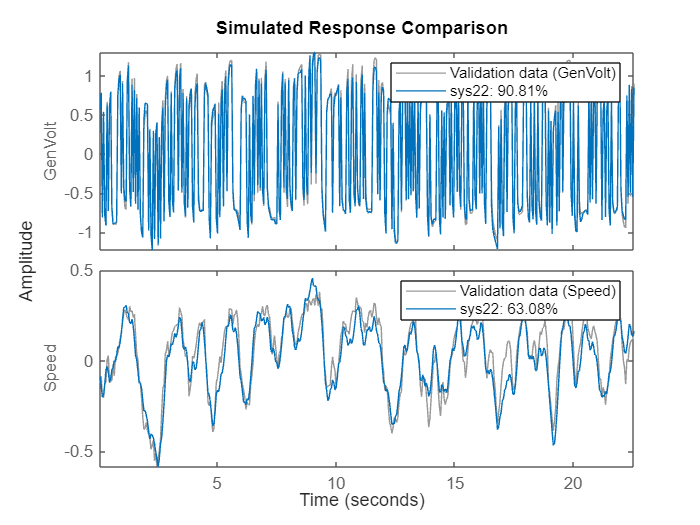

compare(ttsteam, sys22);